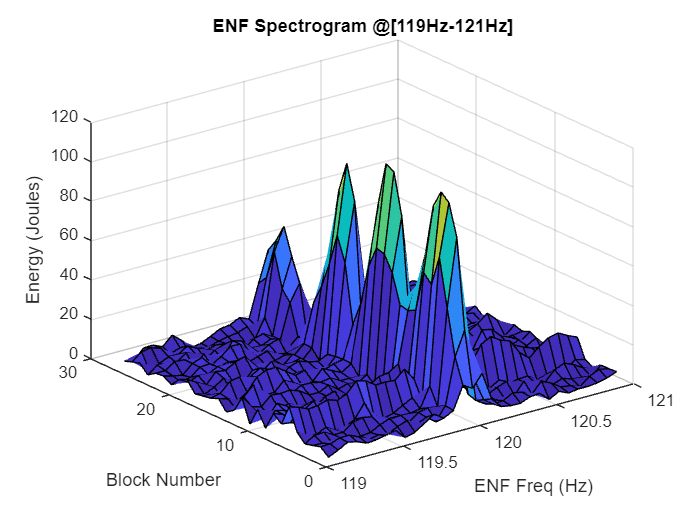

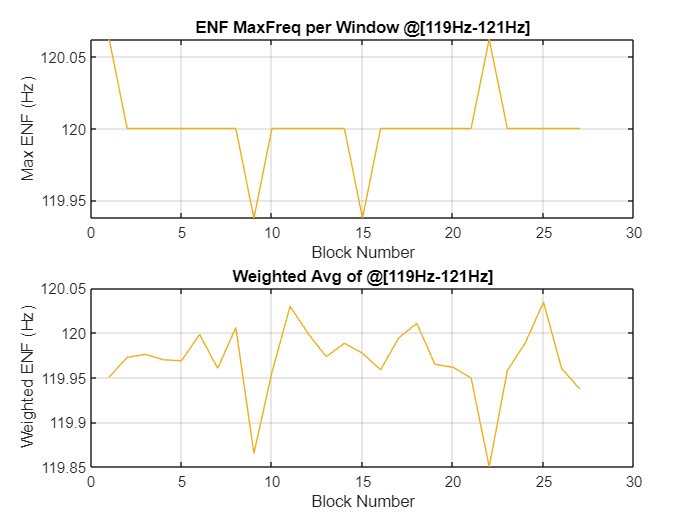

[x1,fs1] = audioread('recording1.wav');
overlap_rate1 = 0.5; %Overlap rate between [0-0.99]
sampleSizeSeconds1 = 16;
segment_size1 = sampleSizeSeconds1*fs1; %Window in #of Samples
padding1 = 0;

window1 = hanning(segment_size1,"periodic");
freq1 = 120;

[ry1, ry2] = enf(x1, fs1 ,segment_size1, padding1, overlap_rate1, window1 , freq1);

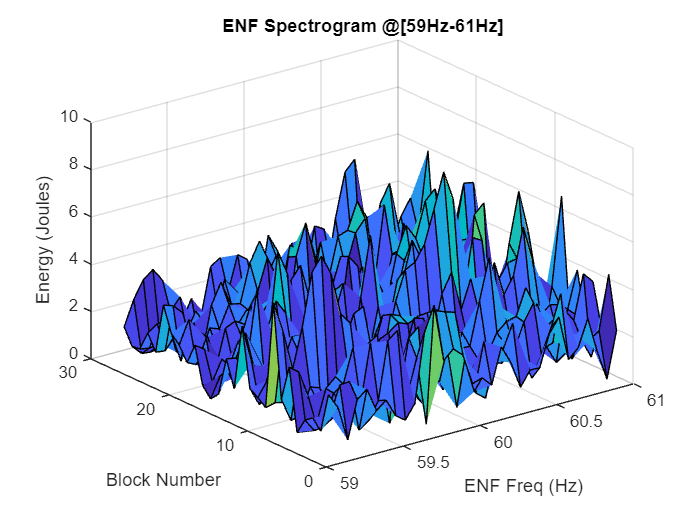

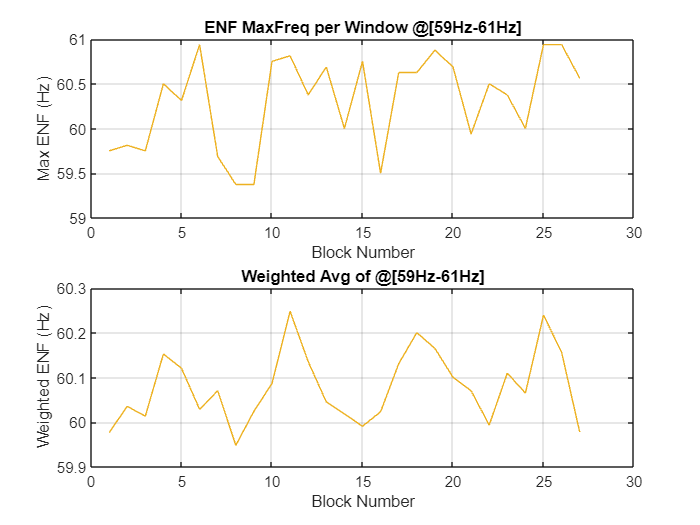

[ry1, ry2] = enf(x1, fs1 ,segment_size1, padding1, overlap_rate1, window1, 60);

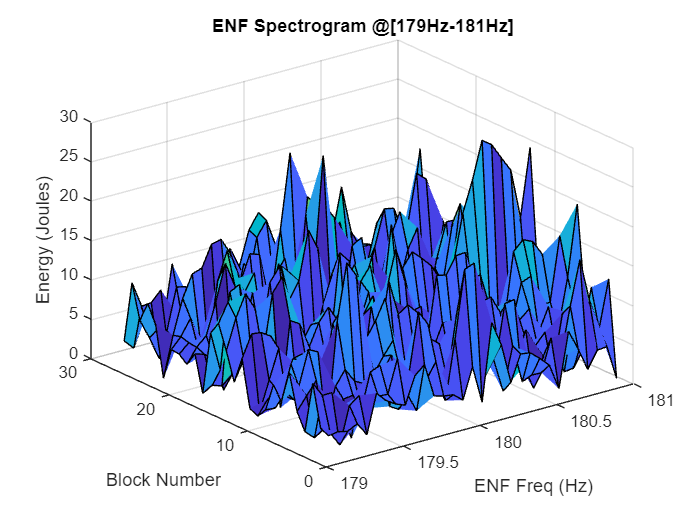

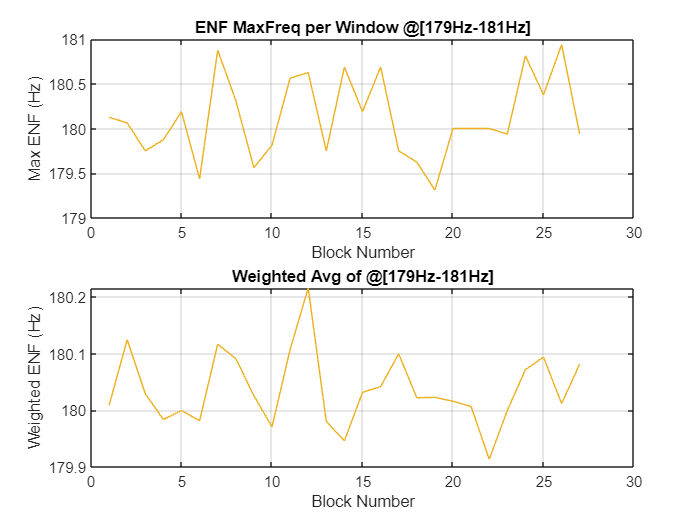

[ry1, ry2] = enf(x1, fs1 ,segment_size1, padding1, overlap_rate1, window1 , 180);

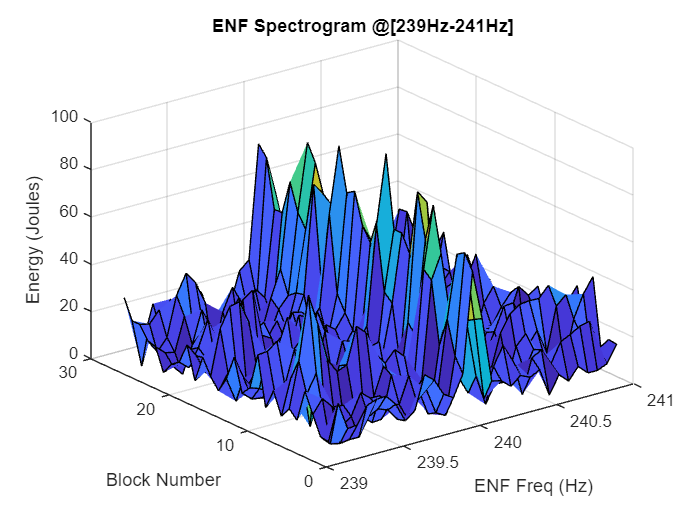

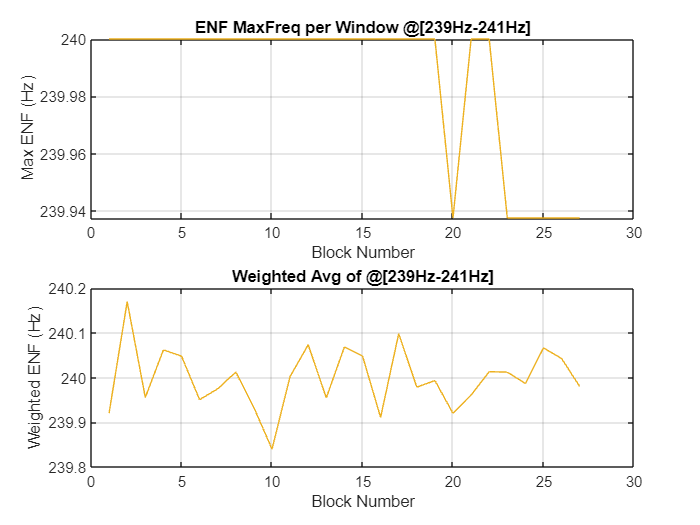

[ry1, ry2] = enf(x1, fs1 ,segment_size1, padding1, overlap_rate1, window1 , 240);

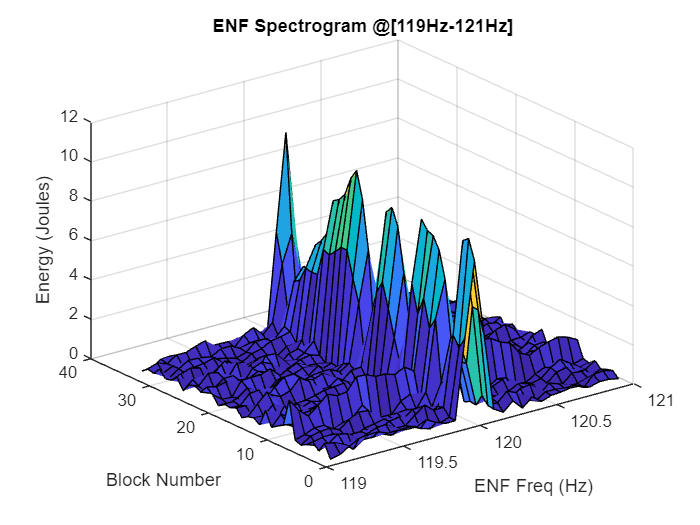

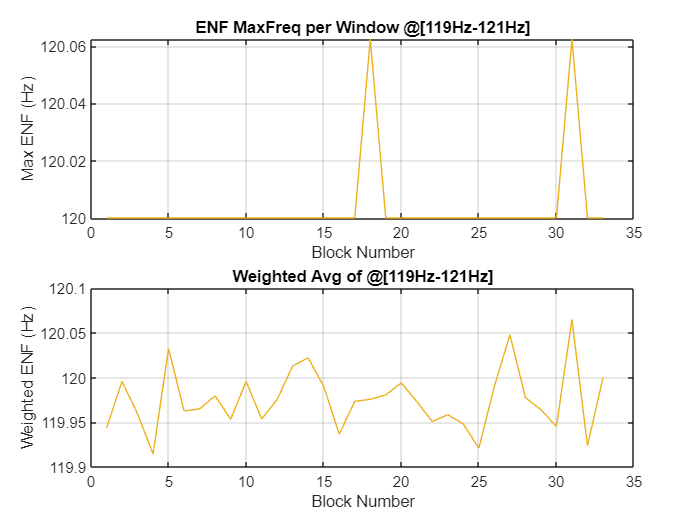

[x2,fs2] = audioread('groundtruth1.wav');
overlap_rate2 = 0.5; %Overlap rate between [0-0.99]

sampleSizeSeconds2 = 16;

segment_size2 = sampleSizeSeconds2*fs2; %Window in #of Samples
padding2 = 0;% segment_size2/2;

window2 = hanning(segment_size2,"periodic");
freq2 = 120;
[gy1, gy2] = enf(x2, fs2 ,segment_size2, padding2, overlap_rate2, window2 , freq2);

[x1,fs1] = audioread('recording1.wav');
overlap_rate1 = 0.5; %Overlap rate between [0-0.99]
sampleSizeSeconds1 = 16;
segment_size1 = sampleSizeSeconds1*fs1; %Window in #of Samples
padding1 = 0;

window1 = hanning(segment_size1,"periodic");
freq1 = 120;

[ry1, ry2] = enf(x1, fs1 ,segment_size1, padding1, overlap_rate1, window1 , freq1);

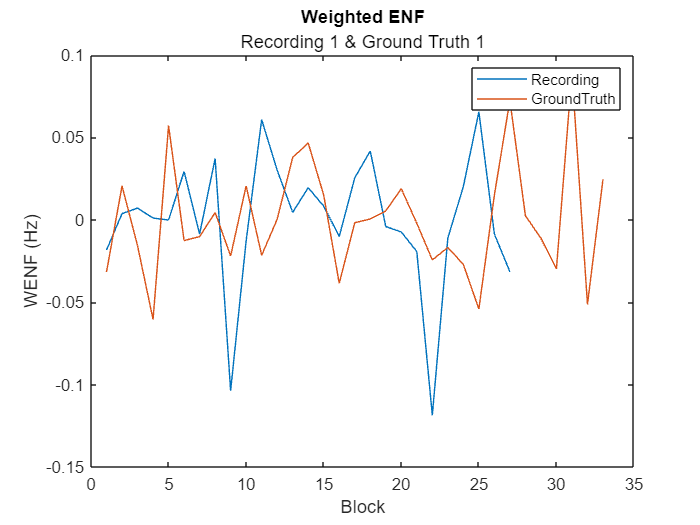

figure
plot(ry2 - mean(ry2));
hold on;
subtitle("Recording 1 & Ground Truth 1");
title("Weighted ENF");
xlabel("Block");
ylabel("WENF (Hz)");
plot(gy2 - mean(gy2));
legend('Recording','GroundTruth');

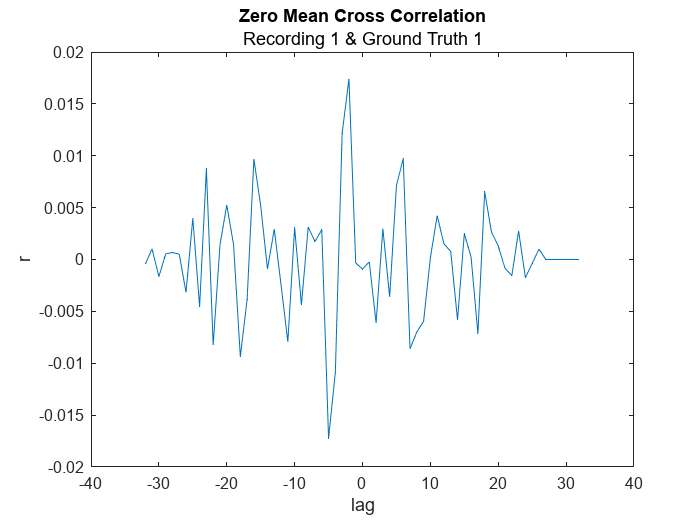


figure
[r,lag] = xcorr(ry2 - mean(ry2),gy2 - mean(gy2));
plot(lag,r);
xlabel("lag");
ylabel("r");
subtitle("Recording 1 & Ground Truth 1");
title("Zero Mean Cross Correlation");

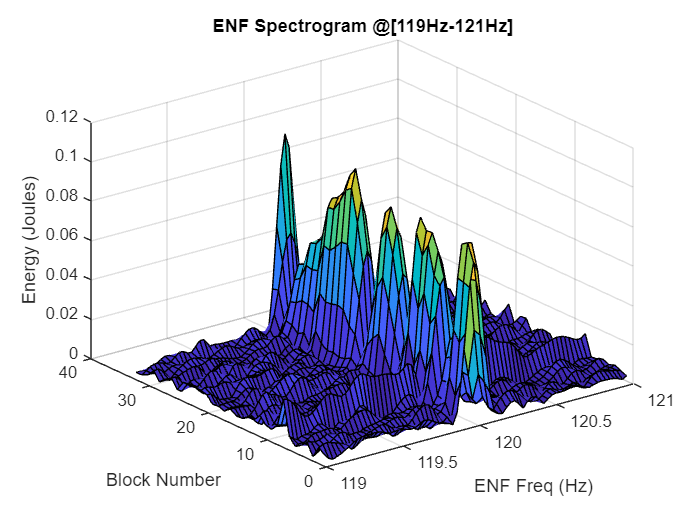

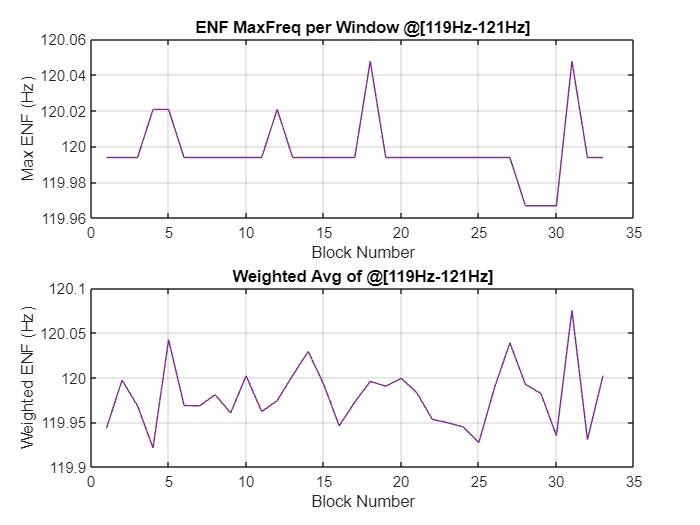

[x1,fs1] = audioread('groundtruth1.wav');
overlap_rate1 = 0.5; %Overlap rate between [0-0.99]
filtx1 = filtfilt(SOS,G,x1);
newx1 = downsample(filtx1,100);

newfs1 = 441;
sampleSizeSeconds1 = 16;

segment_size1 = sampleSizeSeconds1*newfs1; %Window in #of Samples
padding1 = 2.^14 - (newfs1*16);

window1 = hanning(segment_size1,"periodic");
freq1 = 120;

[gy1, gy2] = enf(newx1, newfs1 ,segment_size1, padding1, overlap_rate1, window1 , 120);

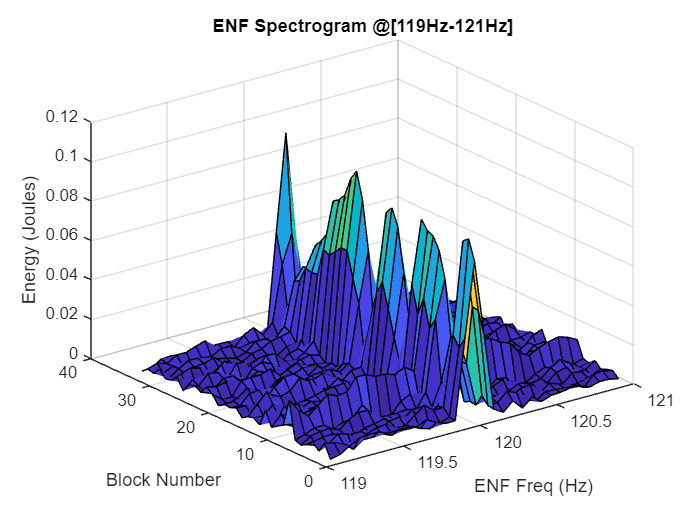

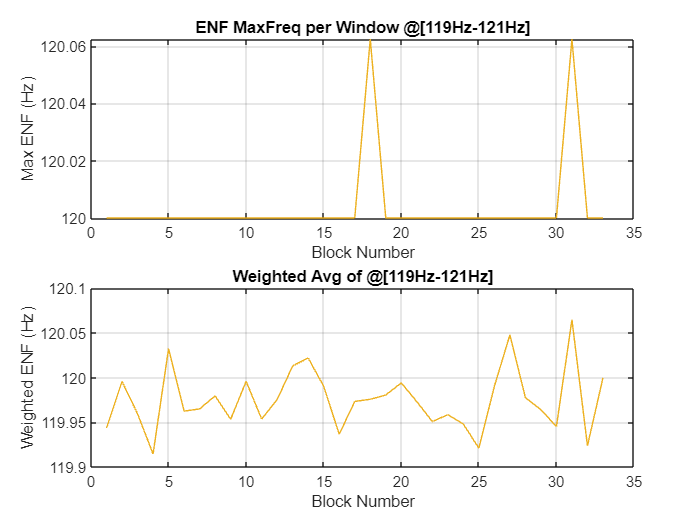

[x2,fs2] = audioread('groundtruth1.wav');
overlap_rate2 = 0.5; %Overlap rate between [0-0.99]
filtx2 = filtfilt(SOS,G,x2);
newx2 = downsample(filtx2,100);

newfs2 = 441;
sampleSizeSeconds2 = 16;

segment_size2 = sampleSizeSeconds2*newfs2; %Window in #of Samples
padding2 = 0;


window2 = hanning(segment_size2,"periodic");
freq2 = 120;

[gy1, gy2] = enf(newx2, newfs2 ,segment_size2, padding2, overlap_rate2, window2 , 120);

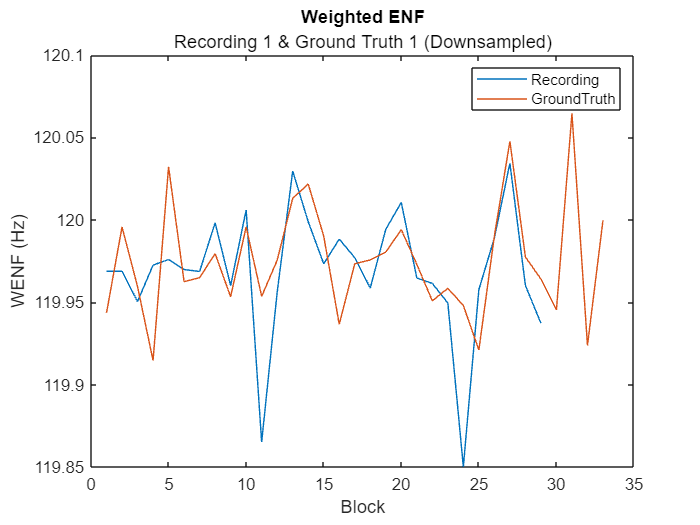

figure

padry2 = padarray(ry2,[0,2],mean(ry2,'all'),'pre');
plot(padry2);
hold on;
subtitle("Recording 1 & Ground Truth 1 (Downsampled)");
title("Weighted ENF");
xlabel("Block");
ylabel("WENF (Hz)");
plot(gy2);
legend('Recording','GroundTruth');

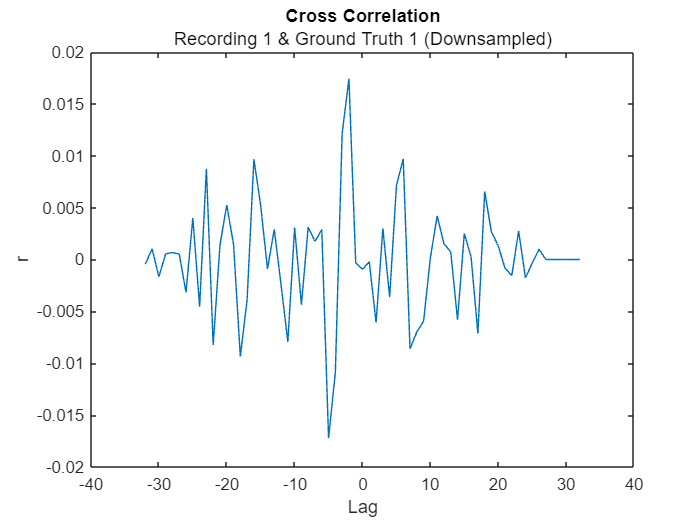

figure
[r,lag] = xcorr(ry2 - mean(ry2),gy2 - mean(gy2));
plot(lag,r);
subtitle("Recording 1 & Ground Truth 1 (Downsampled)");
title("Cross Correlation");
xlabel("Lag");
ylabel("r");

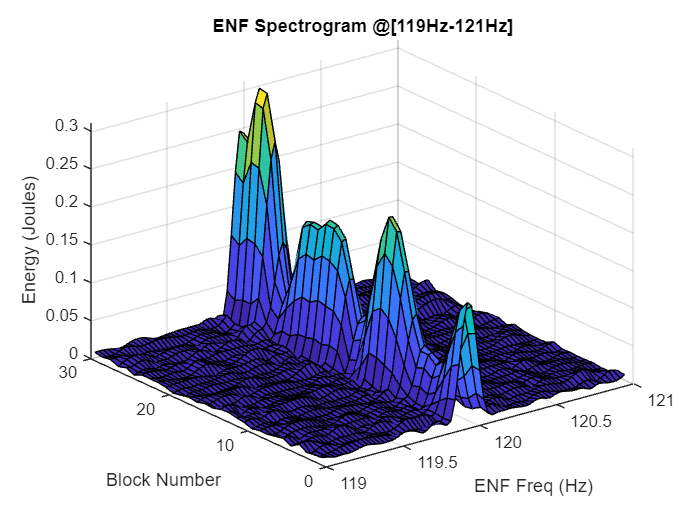

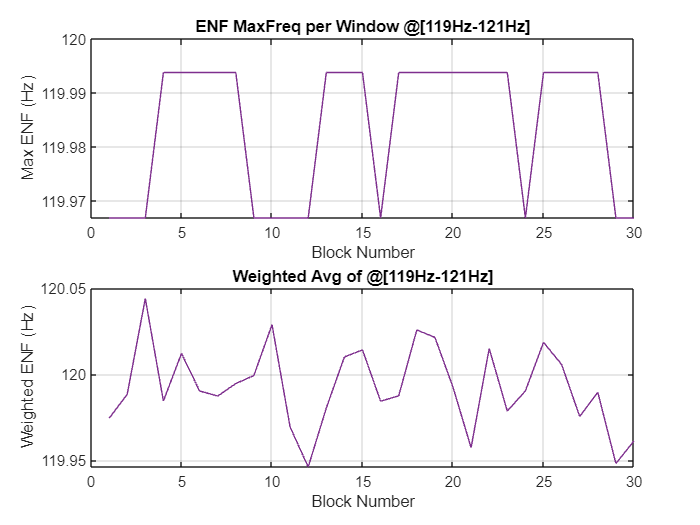

[x2,fs2] = audioread('groundtruth21.wav');
overlap_rate2 = 0.5; %Overlap rate between [0-0.99]
filtx2 = filtfilt(SOS,G,x2);
newx2 = downsample(filtx2,100);

newfs2 = 441;
sampleSizeSeconds2 = 16;

segment_size2 = sampleSizeSeconds2*newfs2; %Window in #of Samples
padding2 = 2.^14 - (newfs2*16);


window2 = hanning(segment_size2,"periodic");
freq2 = 120;

[gy1, gy2] = enf(newx2, newfs2 ,segment_size2, padding2, overlap_rate2, window2 , 120);

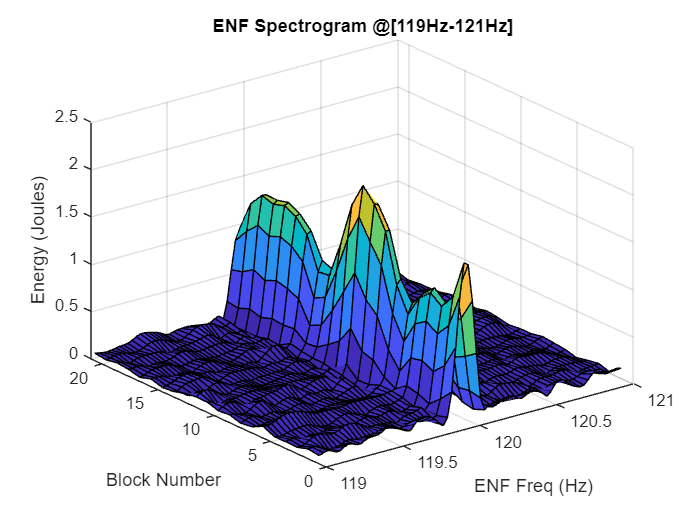

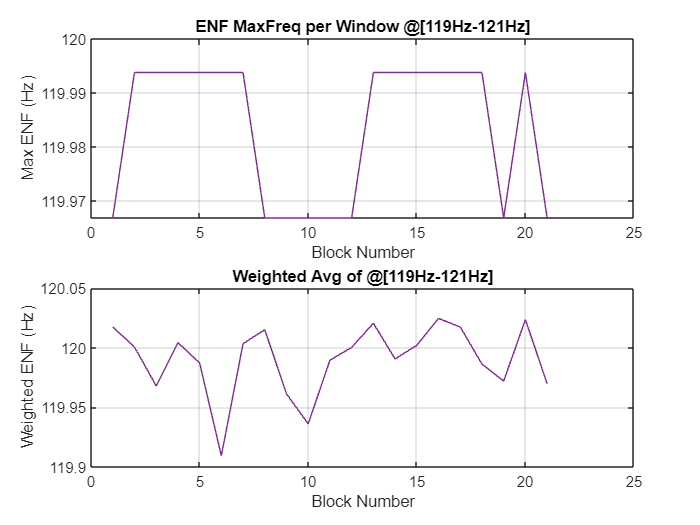

[x1,fs1] = audioread('recording 21.wav');
overlap_rate1 = 0.5; %Overlap rate between [0-0.99]
filtx1 = filtfilt(SOS,G,x1);
newx1 = downsample(filtx1,100);

newfs1 = 441;
sampleSizeSeconds1 = 16;

segment_size1 = sampleSizeSeconds1*newfs1; %Window in #of Samples
padding1 = 2.^14 - (newfs2*16);

window1 = hanning(segment_size1,"periodic");
freq1 = 120;

[ry1, ry2] = enf(newx1, newfs1 ,segment_size1, padding1, overlap_rate1, window1 , 120);

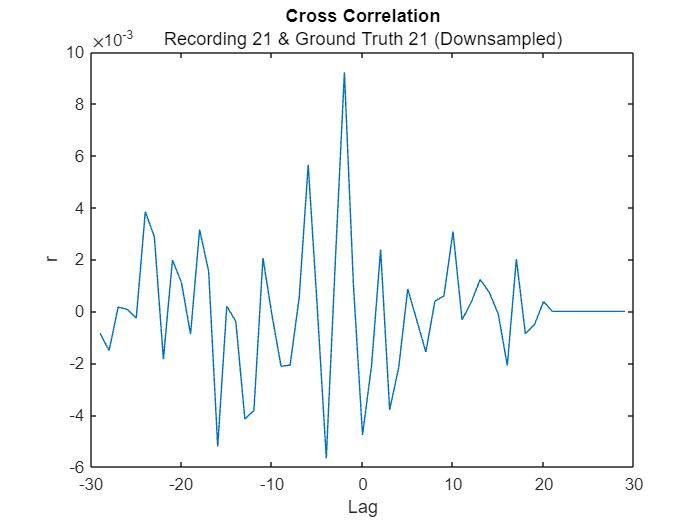

figure
[r,lag] = xcorr(ry2 - mean(ry2),gy2 - mean(gy2));
plot(lag,r);
subtitle("Recording 21 & Ground Truth 21 (Downsampled)");
title("Cross Correlation");
xlabel("Lag");
ylabel("r");